# Tuneable Parameters

% generate_traffic_signal_states

% traffic light desicion model

#  generate_traffic_signal_states

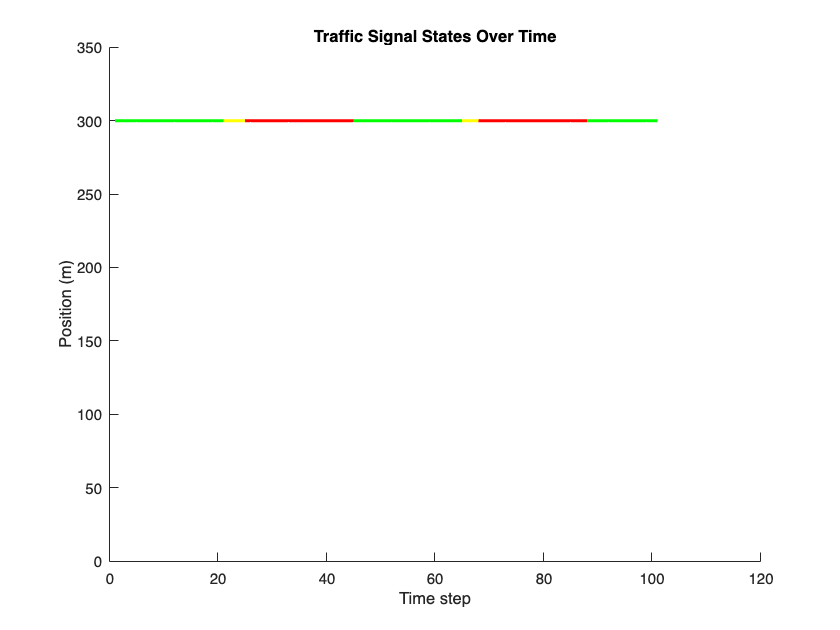

% Script to visualize the traffic signal states
num_iterations = 100; % Number of time steps
num_vehicles = 10; % Number of vehicles (this can be tuned as needed)
red_time = 20; % Red light duration
yellow_time = 3.5; % Yellow light duration
green_time = 20; % Green light duration
d_stop_line = 300; % Stop line position in meters

% Generate traffic signal states
[traffic_signal_states, T_elapsed] = generate_traffic_signal_states(num_iterations, red_time, yellow_time, green_time, num_vehicles);

% Plot traffic light state as a horizontal line at y = d_stop_line
figure;
hold on;

for k = 1:num_iterations
    if traffic_signal_states(k) == "red"
        plot([k k+1], [d_stop_line d_stop_line], 'r', 'LineWidth', 2);
    elseif traffic_signal_states(k) == "yellow"
        plot([k k+1], [d_stop_line d_stop_line], 'y', 'LineWidth', 2);
    elseif traffic_signal_states(k) == "green"
        plot([k k+1], [d_stop_line d_stop_line], 'g', 'LineWidth', 2);
    end
end

xlabel('Time step');
ylabel('Position (m)');
title('Traffic Signal States Over Time');
ylim([0 d_stop_line + 50]);
hold off;

# decision

% Initialization
num_vehicles = 10;
num_time_steps = 50;
red_time = 10;
yellow_time = 3.5;
green_time = 10;
probability_stop = 0.5; % Probability of stopping in dilemma zone

% Initialize states
d = zeros(num_time_steps, num_vehicles);
v = zeros(num_time_steps, num_vehicles);
T_elapsed = zeros(num_time_steps, num_vehicles);
D = strings(num_time_steps, num_vehicles);
S = strings(num_time_steps, 1);

% Initial positions and speeds
d(1, :) = rand(1, num_vehicles) * 100; % Random initial positions
v(1, :) = rand(1, num_vehicles) * 10; % Random initial speeds

% Generate traffic signal states
[traffic_signal_states, T_elapsed] = generate_traffic_signal_states(num_time_steps, red_time, yellow_time, green_time, num_vehicles);
S(:, 1) = traffic_signal_states;

% Simulate over time
for k = 1:num_time_steps-1
    % Simulate vehicle positions and speeds (simple linear model for example)
    d(k+1, :) = d(k, :) + v(k, :);
    v(k+1, :) = v(k, :) + (rand(1, num_vehicles) - 0.5); % Random acceleration
    
    % Calculate decisions
    D(k+1, :) = decision_making(d(k, :), d(k+1, :), v(k, :), v(k+1, :), S(k), S(k+1), T_elapsed(k, :), T_elapsed(k+1, :), D(k, :), probability_stop);
end

% Plot results
figure;
hold on;
colors = {'r', 'g', 'b', 'c', 'm', 'y', 'k', [0.5 0.5 0.5], [0.8 0.2 0.2], [0.2 0.8 0.2]};

for i = 1:num_vehicles
    for k = 1:num_time_steps
        if D(k, i) == "stop"
            plot(k, i, 's', 'Color', colors{i}, 'MarkerFaceColor', 'r'); % Red square for stop
        elseif D(k, i) == "go"
            plot(k, i, 'o', 'Color', colors{i}, 'MarkerFaceColor', 'g'); % Green circle for go
        else
            plot(k, i, '*', 'Color', colors{i}); % Star for undecided or other states
        end
    end
end

xlabel('Time step');
ylabel('Vehicle index');
title('Vehicle Decisions Over Time');
hold off;
